Climb rate

Ts_hev = 1/500;
% Requirments
zeta = 1;
ts2 = 3;
wn = 4/(zeta*ts2)

wn = 1.3333


Ts_climb = 1/(20*wn)

Ts_climb = 0.0375


p_s_want = [-zeta*wn + 1i*wn*sqrt(1-zeta^2);
            -zeta*wn - 1i*wn*sqrt(1-zeta^2)]

p_s_want =    -1.3333
   -1.3333



p_z_want = exp(p_s_want*Ts_hev)

p_z_want =     0.9973
    0.9973


Climb is controllable


C_climb =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 88.1, Ki = 23.9, Ts = 0.002
 
Sample time: 0.002 seconds
Discrete-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 1.3327
           PhaseMargin: 60.0000


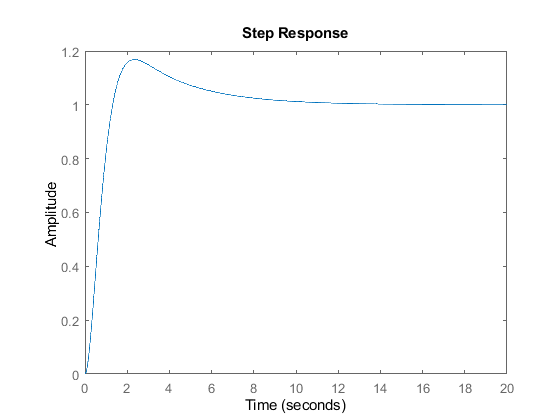


% Plant
A_hev = [-1/t_P,  0, 0;
            1/m(1), 0, 0;
            0,     -1, 0];

b_hev = [1/t_P; 0; 0];
c_climb = [0, 1, 0];
d_climb = 0;

sysC = ss(A_hev,b_hev,c_climb,d_climb);
sysD_climb = c2d(sysC,Ts_hev,'zoh');
F_hev = sysD_climb.A;
G_hev = sysD_climb.B;

% Controllability
U_test = ctrb(F_hev,G_hev);
if det(U_test) == 0
    disp('Climb is NOT controllable')
else
    disp('Climb is controllable')
    
%     F_bar = [F,zeros(2,1); c_climb*F, 1];
%     g_bar = [G;c_climb*G];
% 
%     kclimb = acker(F_bar,g_bar,[p_z_want;0.9]);
%     kp_climb = kclimb(1:2)
%     ki_climb = kclimb(3)
%     Nbar_climb = (ki_climb*0.9)/(1-0.9)
    
    [C_climb,info] = pidtune(sysD_climb,'PI')
    step(feedback(C_climb*sysD_climb,1))
    
    % Equivalent plant
    A_clm = [A_hev-b_hev*C_climb.Kp*c_climb, b_hev*C_climb.Ki;
             -c_climb              , 0];
    b_clm = [b_hev*C_climb.Kp;1];
end

Altitude

Alt is controllable


C_alt =
 
  Kp = -0.485
 
P-only controller.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 0.5700
           PhaseMargin: 68.2755


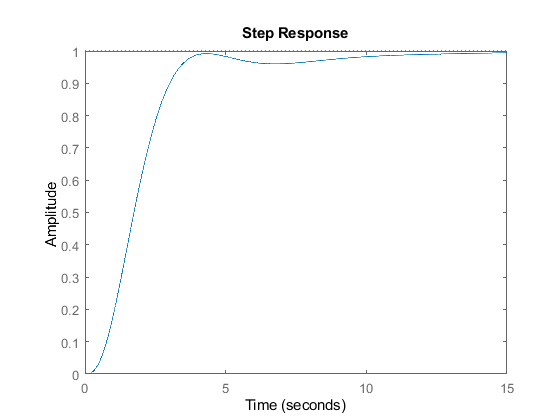

% Plant
c_alt = [0,0,1,0];
d_alt = 0;

sysC = ss(A_clm,b_clm,c_alt,d_alt);
sysD_alt = c2d(sysC,Ts_hev,'zoh');
% F_alt = sysD_alt.A;
% G_alt = sysD_alt.B;

% Controllability
U_test = ctrb(F_hev,G_hev);
if det(U_test) == 0
    disp('Alt is NOT controllable')
else
    disp('Alt is controllable')
            [C_alt, info] = pidtune(sysD_alt,'P',0.57)
    step(feedback(C_alt*sysD_alt,1))
end